# ACM 11: Week 5 In-class exercise 3

In this exercise we will explore how convergence to different minima occurs when we change the step size and initial condition. Consider the function with multiple distinct minima:


$$f\left(x,y\right)=\left(x-10x^3 -5y^3 \right)e^{-x^2 -y^2 }$$


We will consider the unconstrained optimization problem for $f\left(x,y\right)\;$to find its minima:


$$\min_{(x,y) \in \mathbb{R}^{2}}(x-10x^3-5y^3)e^{-x^2-y^2}$$


The code block below sets up the objective function and its gradient, then plots the function as a surface and plots the function contours. The true minima are labeled on the contours.

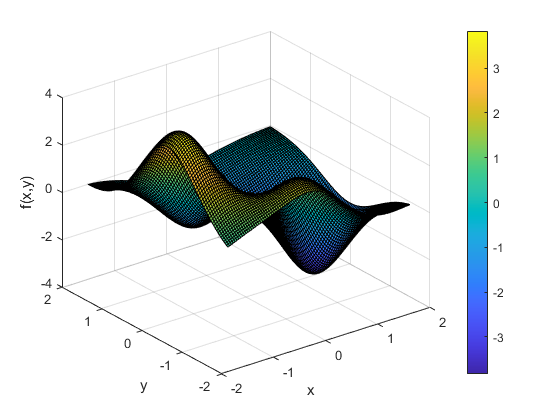

% Set up the optimization problem
% Grid for plots
[x,y] = meshgrid(linspace(-1.5,2),linspace(-1.5,2)); 

% Objective function
f = @(x,y) (x-10*x.^3-5*y.^3).*exp(-x.^2-y.^2); 

% Gradient
df = @(x,y) [exp(-x.^2-y.^2)*(20*x.^4-32*x.^2+10*x.*y.^3+1); y.*exp(-x.^2-y.^2)*(20*x.^3-2*x+5*y.*(2*y.^2-3))];

figure(1); clf
surf(x,y,f(x,y)); colorbar
xlabel('x'); ylabel('y'); zlabel('f(x,y)')

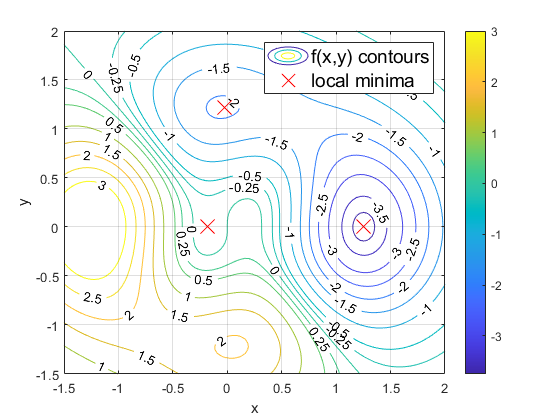


% Contour plot
figure(2); clf;
[c,h] = contour(x,y,f(x,y),[-4,-3.75,-3.5,-3,-2.5,-2,-1.5,-1,-0.5,-0.25,0,0.25,0.5,1,1.5,2,2.5,3, 4]); %contour plot
clabel(c,h)
colorbar
xlabel('x')
ylabel('y')
grid on; hold on
% Label the "exact" solutions
a = [-0.178564904763336; 1.252243816030593; -0.026655634583497];
b = [0; 0; 1.223861708341486]; 
plot(a,b,'rx','MarkerSize',15);
legend('f(x,y) contours','local minima','FontSize',14)

**(0) Please include all the names of your group members here:**

**Kyle McGraw**

**(1) We will use the steepest descent method without a line search. Let's explore what happens by changing the initial guess coordinates **$\left(x_0 ,y_0 \right)$** using the drop-down menu and observe the computed minimum.**

The code block below implements the steepest descent method for you and plots the resulting optimization path. Notice that the step direction is always perpendicular to the contours (you might remember from multivariable calculus that the gradient is perpendicular to the contours). Additionally, the code also plots the convergence of the optimization path to the nearest minima of the final computation.

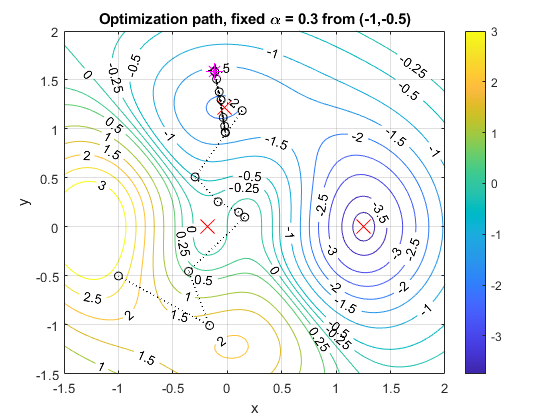

% Initialize plot 
figure(3); clf;
[c,h] = contour(x,y,f(x,y),[-4,-3.75,-3.5,-3,-2.5,-2,-1.5,-1,-0.5,-0.25,0,0.25,0.5,1,1.5,2,2.5,3, 4]); %contour plot
clabel(c,h)
colorbar
xlabel('x')
ylabel('y')
grid on; hold on
% Label the "exact" solutions
a = [-0.178564904763336; 1.252243816030593; -0.026655634583497];
b = [0; 0; 1.223861708341486];
plot(a,b,'rx','MarkerSize',15); 

% Set the parameters
x0 = -1; % initial x guess
xn = x0;
y0 = -0.5; % initial y guess
yn = y0;
Nmax = 250; %maximum iterations

iterates_1 = zeros(Nmax,2); % initialize array for storing error
alpha = 0.3; % varying step size
for i = 1:Nmax
    g = df(xn,yn); % evaluate gradient

    figure(3);
    % Plot the optimization path    
    plot([xn, xn-alpha*g(1)],[yn yn-alpha*g(2);],'k:','LineWidth',1);
    hold on
    plot(xn, yn,'ko')
    xn = xn - alpha*g(1);  % go down the gradient in x direction
    yn = yn - alpha*g(2);  % go down the gradient in y direction 
    iterates_1(i,:) = [xn yn];

    % Convergence check
    if norm(df(xn,yn)) < 1e-6
        break
    end
end
iterates_1 = iterates_1(1:i,:);
plot(xn, yn,'m*','MarkerSize',12)

xlabel('x')
ylabel('y')
title(['Optimization path, fixed \alpha = ',num2str(alpha),' from (',num2str(x0),',',num2str(y0),')'])

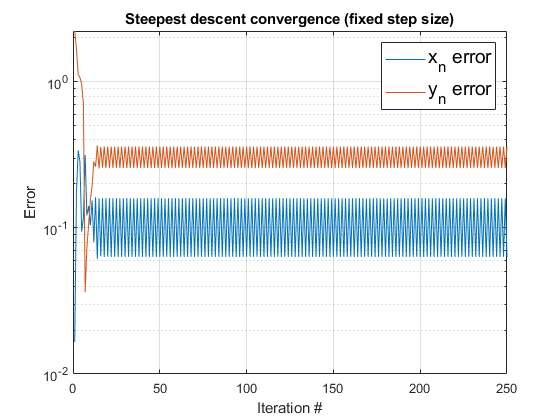


% Plot the decay of the error's absolute value in two directions to the
% closest final minima
[xFinalError, aIdx] = min(abs(xn-a));
aClosest = a(aIdx);
[yFinalError, bIdx] = min(abs(yn-b));
bClosest = b(bIdx);

figure(4); clf
semilogy(abs(iterates_1(:,1)-aClosest)); hold on 
semilogy(abs(iterates_1(:,2)-bClosest)); grid on
xlabel('Iteration #')
ylabel('Error')
legend('x_n error','y_n error','FontSize',14)
title('Steepest descent convergence (fixed step size)','FontSize',18)
set(gca,'fontsize',10);

**1a: Start with **$\alpha =0\ldotp 1$** and vary the initial guess coordinates **$\left(x_0 ,y_0 \right)$**. Does the gradient descent algorithm always converge to the same minimum? Explain why or why not.**

It does not because there are multiple minimums, so it will go to the closest.

**1b: Explain why the initial guess is important for finding the desired minimum is there are multiple minima.**

Because there are multiple minimums, we need to make sure our initial guess is on the slope towards our desired minimum.

**(2)  Next, let's explore what happens by changing the fixed step size **$$\alpha$$** using the drop-down menu in the code block above and observe the computed minimum.**

**2a: When you take a very small **$\alpha$, **which minima does the algorithm converge to? **

With small a, the algorithm converges to the closest.

**2b: What can happen when you take a large **$\alpha$**? In contrast to small **$\alpha$**, which minima can the algorithm approach?**

**With large a, it can approach a minimum that is not the closest/down the gradient, but can go to a further one because of the large jumps.**

**2c: Explain why step size is important for finding the desired minimum is there are multiple minima. **

**Step size is important because you don't want to over shoot your minimum and end up at a different one.**